%variables
k1 = 4.66;
k2 = 4.66;
m1 = 0.0917;
m2 = 0.0765;
x1_0 = 100;
x2_0 = 50;
T = 10;
N = 1000;
% A matrix 
A = [0 1 0 0; (-k1/m1 -k2/m1) 0 k2/m1 0; 0 0 0 1; k2/m2 0 -k2/m2 0];



[x,y,t_est] = IEMsolver(A,x1_0,x2_0,T,N)

ans =          0  -76.2268 -151.5241 -224.9720 -295.6758 -362.7788 -425.4736 -483.0135 -534.7224 -580.0045 -618.3519 -649.3520 -672.6925 -688.1659 -695.6722 -695.2196 -686.9249 -671.0106 -647.8027 -617.7249 -581.2928 -539.1067 -491.8424 -440.2419 -385.1028 -327.2664 -267.6063 -207.0157 -146.3945  -86.6370  -28.6187   26.8160   78.8654  126.7824  169.8846  207.5643  239.2968  264.6479  283.2801  294.9572  299.5474  297.0255  287.4730  271.0765  248.1256  219.0081  184.2049  144.2827   99.8859   51.7275


ans =          0   30.4575   60.2652   88.7803  115.3794  139.4675  160.4869  177.9256  191.3248  200.2864  204.4784  203.6403  197.5874  186.2136  169.4936  147.4832  120.3193   88.2184   51.4736   10.4511  -34.4149  -82.6277 -133.6349 -186.8361 -241.5908 -297.2274 -353.0524 -408.3600 -462.4417 -514.5964 -564.1399 -610.4147 -652.7989 -690.7151 -723.6385 -751.1040 -772.7133 -788.1401 -797.1347 -799.5280 -795.2337 -784.2495 -766.6579 -742.6243 -712.3956 -676.2965 -634.7254 -588.1489 -537.0954 -482.1482


x =   100.0000   99.6189   98.4778   96.5907   93.9806   90.6794   86.7271   82.1718   77.0686   71.4790   65.4699   59.1131   52.4838   45.6599   38.7208   31.7465   24.8163   18.0076   11.3954    5.0506   -0.9603   -6.5766  -11.7440  -16.4152  -20.5508  -24.1193  -27.0982  -29.4737  -31.2408  -32.4038  -32.9757  -32.9783  -32.4415  -31.4029  -29.9076  -28.0068  -25.7577  -23.2221  -20.4657  -17.5572  -14.5670  -11.5665   -8.6265   -5.8167   -3.2043   -0.8533    1.1769    2.8321    4.0641    4.8315


y =    50.0000   50.1523   50.6075   51.3560   52.3816   53.6620   55.1695   56.8705   58.7268   60.6959   62.7316   64.7847   66.8038   68.7361   70.5280   72.1260   73.4779   74.5328   75.2429   75.5631   75.4529   74.8760   73.8016   72.2047   70.0665   67.3746   64.1236   60.3153   55.9582   51.0682   45.6680   39.7870   33.4613   26.7326   19.6483   12.2610    4.6273   -3.1923  -11.1347  -19.1345  -27.1250  -35.0391  -42.8101  -50.3725  -57.6631  -64.6212  -71.1899  -77.3168  -82.9541  -88.0600


t_est =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


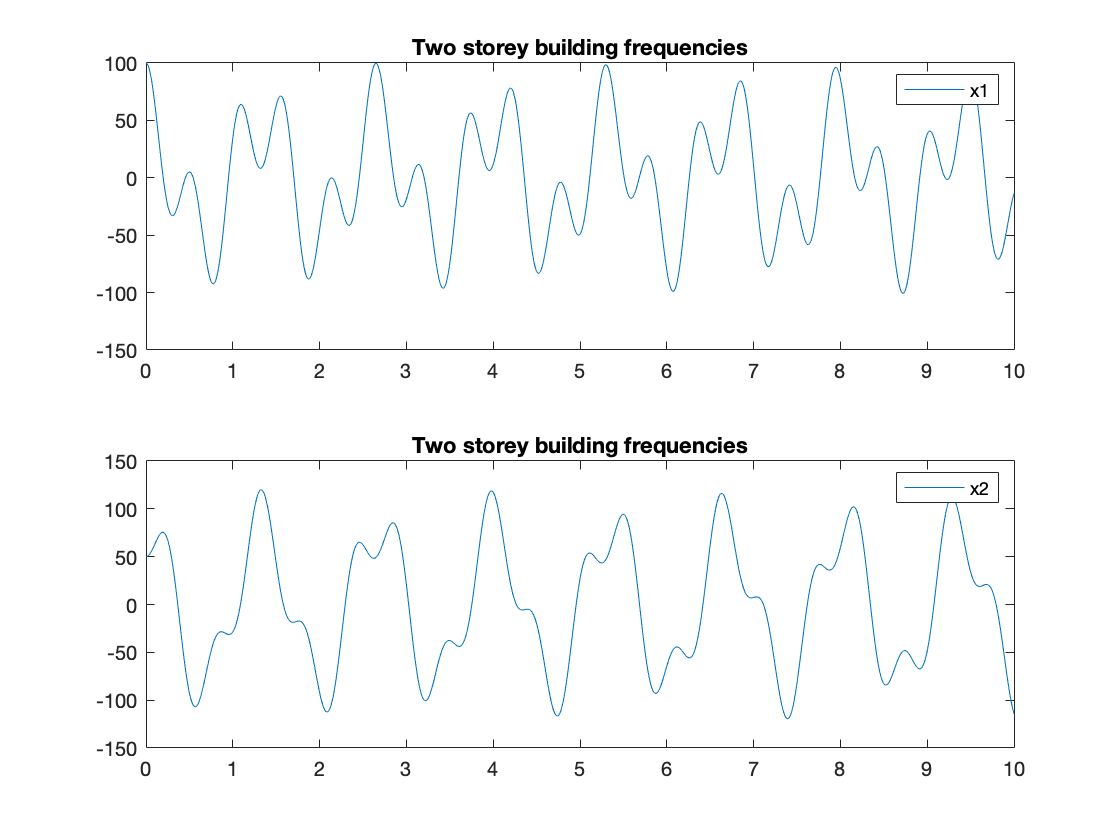



figure 
subplot(2,1,1)
plot(t_est,x)
legend("x1")
title("Two storey building frequencies")
subplot(2,1,2)
plot(t_est,y)
legend("x2")
title("Two storey building frequencies")

eig(A)

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i


Improved Eulers Method 

function [x,y,t] = IEMsolver(A,x_0,y_0,T,N)
   
    dt = T/N;
    t = 0:dt:T;
    
    SOL = NaN(4,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = 0;
    SOL(3,1) = y_0;
    SOL(4,1) = 0;
    for(k = 2:length(t))
        temp = SOL(:,k-1) + dt*A*SOL(:,k-1);
        %average over the two steps
        SOL(:,k) = SOL(:,k-1) + (dt*A*SOL(:,k-1) + dt*A*temp) / 2;
    end
    x = SOL(1,:);
    y = SOL(3,:);
    SOL(2,:);
    SOL(4,:);
end